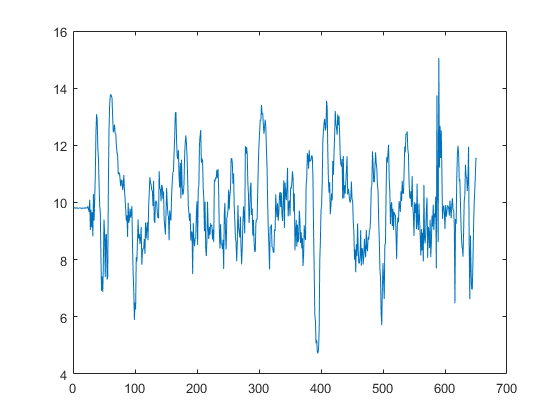

close all;
x = load("variable_a5.txt");
y = load("variable_b5.txt");
y = normalize(y, "range");

%x = x(40:550);
%y = y(40:550);

plot(x+9.81)

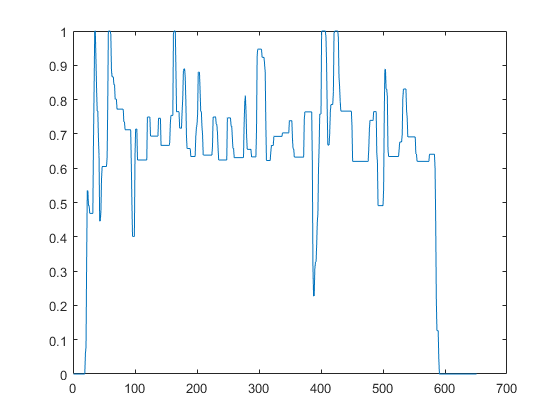

plot(y)

x = x + 9.81

x =    9.816351245600000
   9.818586051500001
   9.807613166600001
   9.799466241000001
   9.805836782500000
   9.808755127800001
   9.817555772100000
   9.789646427000001
   9.809141044020000
   9.805522202300001


format long
b1 = x\y

b1 =    0.060596180023130


yCalc1 = b1*x;
scatter(x,y)
hold on
plot(x,yCalc1)
xlabel('acceleration')
ylabel('pwm_speeds')
grid on
X = [ones(length(x),1) x];
b = X\y

b =    0.127464031249784
   0.048048954459954


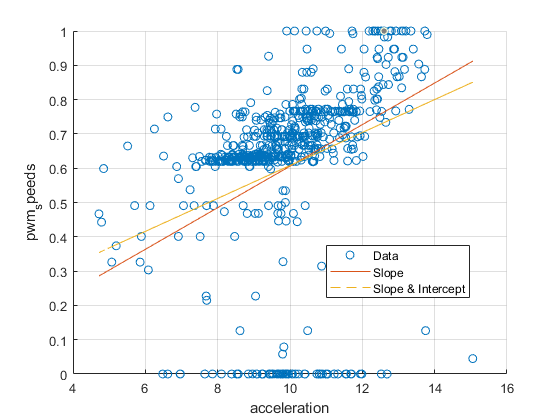

yCalc2 = X*b;
plot(x,yCalc2, '--')
legend('Data','Slope','Slope & Intercept','Location','best');
hold off


% normaliser pwm signal - Det har vi gjort nu :) 
% Tag højde for massen hvis vi hiver det ud i newton - Det gør de selv i
% blokken der styrer polynomiet som vi er ved at lave. 
% Fix tyngdekraften siden signalet ikke er 0 når den står stille i luften
% men 9.81.